**INITIAL CLEARANCE OF THE WORKSPACE**

clear all;

**FILE IMPORT AND UNPACK**

% load camera parameters
LoadCameraParameters('./camera_parameters_lab.mat');

% read the image of the checkerboard
image = imread('.\test images\checkerboard_lab_rgb.png');

% define the physical dimensions of a checkerboard square in millimeters.
edgeLength = 30;

% construct the 42 checkerboard points from points 1 and 6 in the rcs
boardOriginRCS = [357.2  65.4]; % point 1 in rcs
boardCornerRCS = [353.4 -85.62]; % point 6 in rcs

global cameraParameters;

transform = TransformPCStoCCS(image, cameraParameters, edgeLength);

Score: 100.62 %



transform.extendToRCS(boardOriginRCS, boardCornerRCS);

Distance CCS to RCS: 779 mm



% define a set of pixel coordinates for testing
testPointsPCS = [cameraParameters.PrincipalPoint; 
    cameraParameters.PrincipalPoint + 150;
    0 0];

% apply full transformation on the testing set
testPointsRCS = transform.apply(testPointsPCS)

testPointsRCS =   676.5938  385.3099         0
  651.7514  553.3143         0
  907.6872 -165.2113         0


**VISUALIZATION**

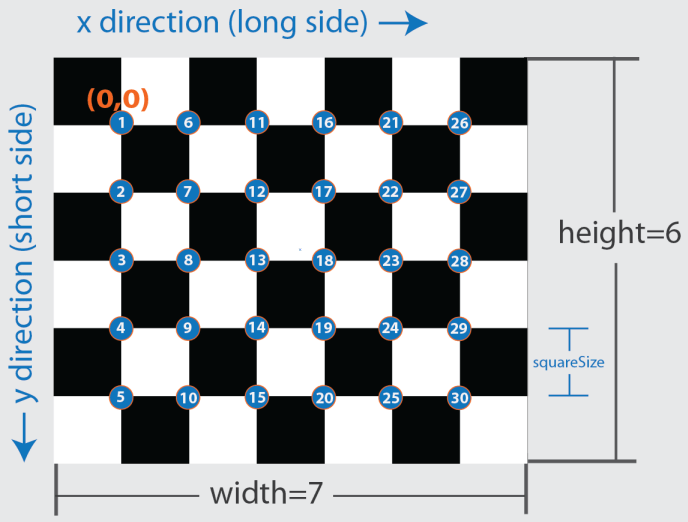

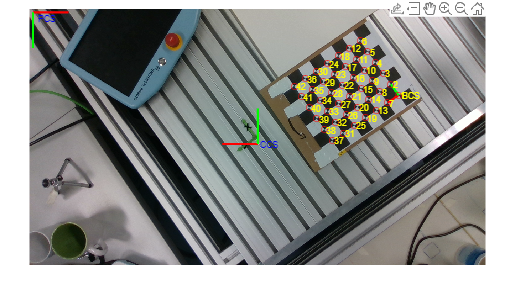

% display the image and plot the detected corners and axes
transform.show(image);